f = @(x) 2.*x.^3 + 3.*x.^2 + x + 2

f = function_handle with value:
    @(x)2.*x.^3+3.*x.^2+x+2


t = linspace(-3, 3, 101)

t =    -3.0000   -2.9400   -2.8800   -2.8200   -2.7600   -2.7000   -2.6400   -2.5800   -2.5200   -2.4600   -2.4000   -2.3400   -2.2800   -2.2200   -2.1600   -2.1000   -2.0400   -1.9800   -1.9200   -1.8600   -1.8000   -1.7400   -1.6800   -1.6200   -1.5600   -1.5000   -1.4400   -1.3800   -1.3200   -1.2600   -1.2000   -1.1400   -1.0800   -1.0200   -0.9600   -0.9000   -0.8400   -0.7800   -0.7200   -0.6600   -0.6000   -0.5400   -0.4800   -0.4200   -0.3600   -0.3000   -0.2400   -0.1800   -0.1200   -0.0600


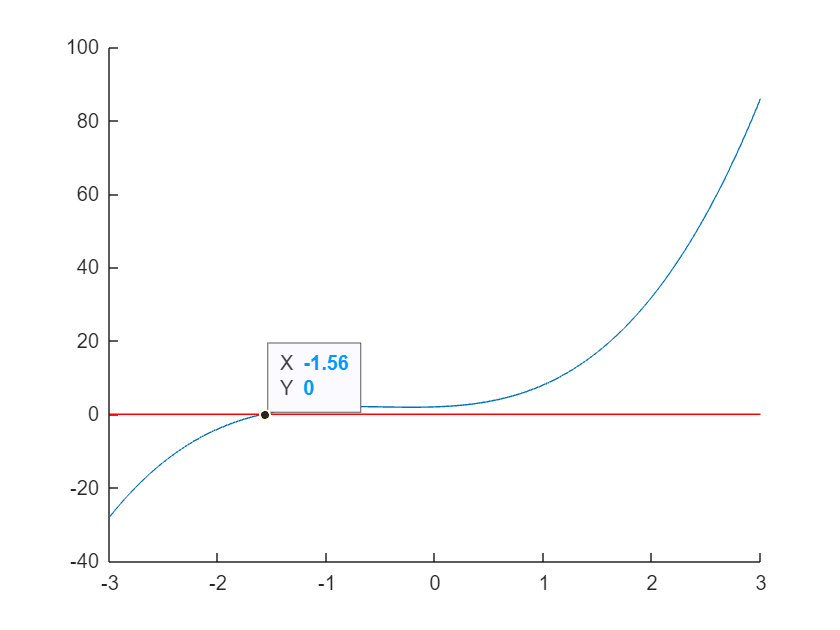

close all;
figure;
hold on;
plot(t, f(t))

plot(t, zeros(size(t)), 'r')

% first test: 
x0 = 2;
y0 = f(x0)

y0 = 32


h = 0.01;
x1 = x0 + h;
y1 = f(x1)

y1 = 32.3715

df1 = (y1-y0)/h

df1 = 37.1502


x2 = x1 - y1/df1

x2 = 1.1386

x_prev = 2;
y_prev = f(x_prev);

x = x_prev + 0.01;
y = f(x);

dy = (y-y_prev)/(x-x_prev);

x_prev = x;
y_prev = y;


for i = (1:100)
    if abs(y) < 1e-4
        "broke at i = " + string(i) 
        break
    end
    x = x_prev - y/dy;
    y = f(x);
    dy = (y-y_prev)/(x-x_prev);
    x_prev = x;
    y_prev = y;
    [x,y]
end

ans =     1.1386    9.9805


ans =     0.7502    5.2833


ans =     0.3134    2.6695


ans =    -0.1328    1.9154


ans =    -1.2661    1.4837


ans =    -5.1613 -198.2325


ans =    -1.2951    1.3924


ans =    -1.3220    1.3001


ans =    -1.7019   -0.8711


ans =    -1.5495    0.2130


ans =    -1.5794    0.0244


ans =    -1.5833   -0.0008


ans =    -1.5832    0.0000


ans = "broke at i = 14"

fzero(f, 2)

ans = -1.5832